
clear; clc; close all;




[y1, fs] = audioread("C:\Users\18237\Desktop\C_01_02(1).wav");
y1 = y1(:)';

vocoder_input = y1;

L = length(vocoder_input);
t = (0:L-1) / fs;
f = fs * (0:floor(L/2)) / L;



N = 4;
f_min = 200;
f_max = 7000;
LPF_cut_freq = 50;

[b_lpf, a_lpf] = butter(2, LPF_cut_freq / (fs/2));



pass_band_lower = f_min : (f_max - f_min) / N : f_max - (f_max - f_min) / N;
pass_band_upper = f_min + (f_max - f_min) / N : (f_max - f_min) / N : f_max;
center_freq = (pass_band_lower + pass_band_upper) / 2;

band_table = table((1:N)', pass_band_lower', pass_band_upper', center_freq', ...
    'VariableNames', {'Band', 'Lower_Hz', 'Upper_Hz', 'Center_Hz'});

disp('Band division result:');

Band division result:


disp(band_table);

    Band    Lower_Hz    Upper_Hz    Center_Hz
    ____    ________    ________    _________

     1         200        1900        1050   
     2        1900        3600        2750   
     3        3600        5300        4450   
     4        5300        7000        6150   



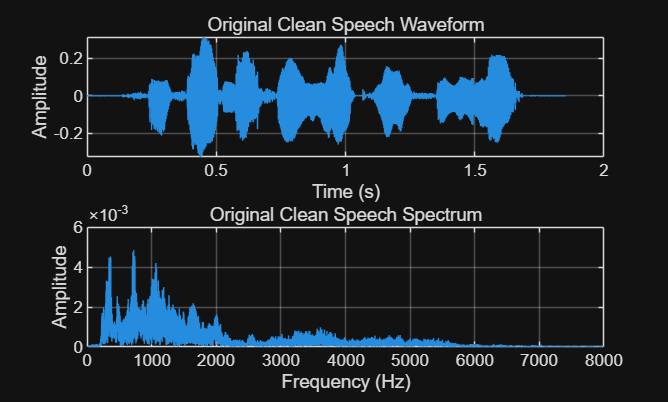


writetable(band_table, 'Additional_Task3_band_table.csv');



figure('Name', 'Original Clean Speech');

subplot(2,1,1);
plot(t, vocoder_input);
title('Original Clean Speech Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
Y_fft = fft(vocoder_input);
P = abs(Y_fft / L);
P_single = P(1:floor(L/2)+1);
P_single(2:end-1) = 2 * P_single(2:end-1);

plot(f, P_single);
title('Original Clean Speech Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, 8000]);
grid on;

exportgraphics(gcf, 'Additional_Task3_original_clean_speech.png', 'Resolution', 300);  


Running filter type: Butterworth IIR


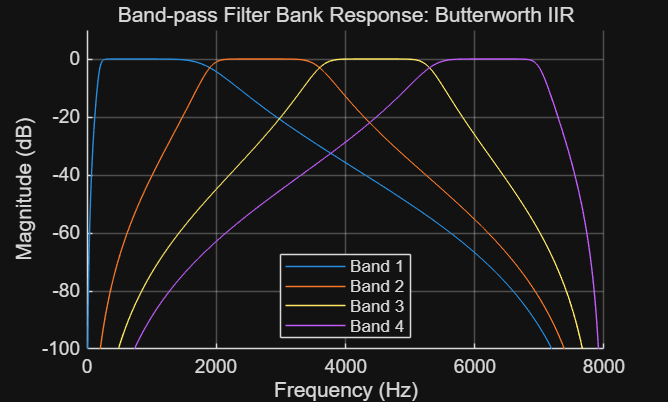

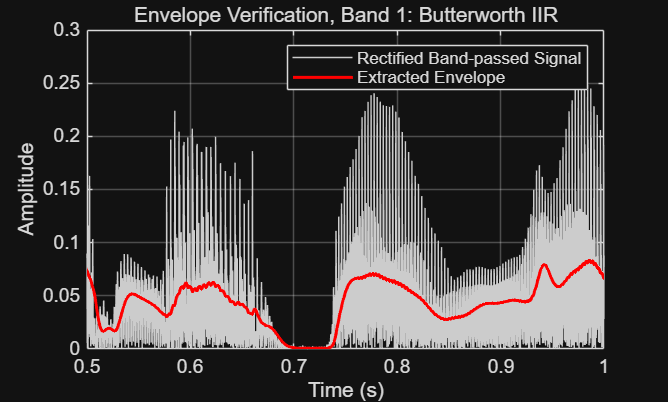

Butterworth IIR: input energy = 87.0316, before normalization = 28.7500, after normalization = 87.0316


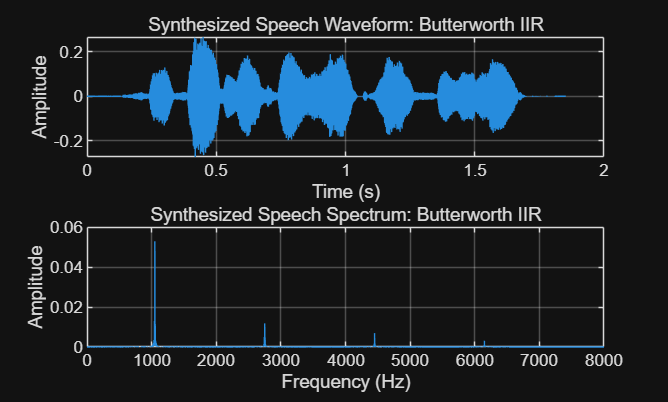


Running filter type: Chebyshev Type I IIR


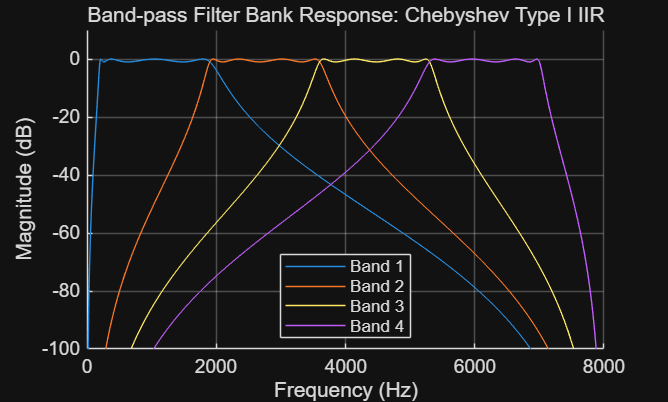

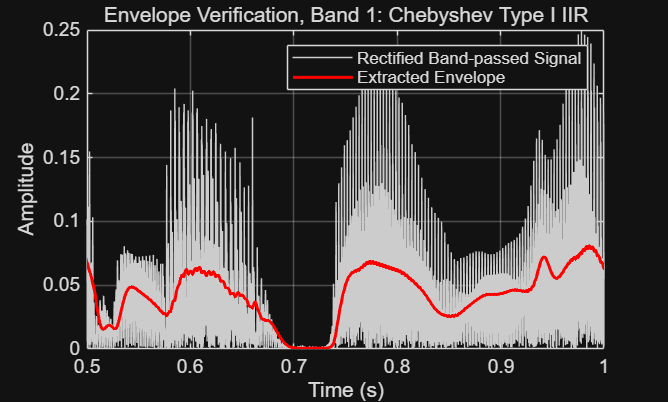

Chebyshev Type I IIR: input energy = 87.0316, before normalization = 26.8198, after normalization = 87.0316


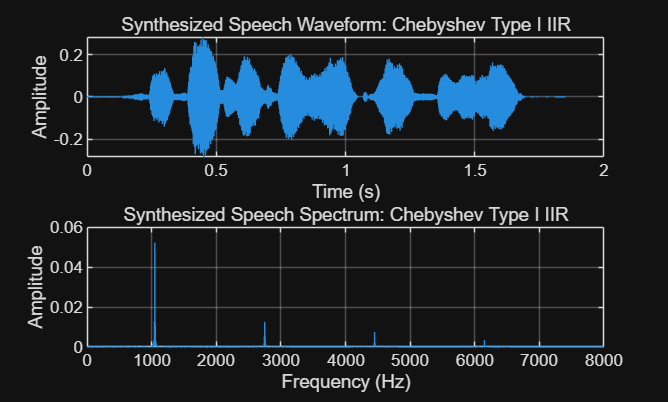


Running filter type: Chebyshev Type II IIR


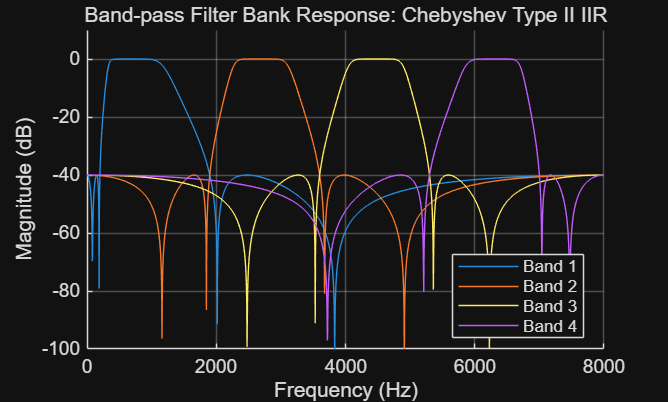

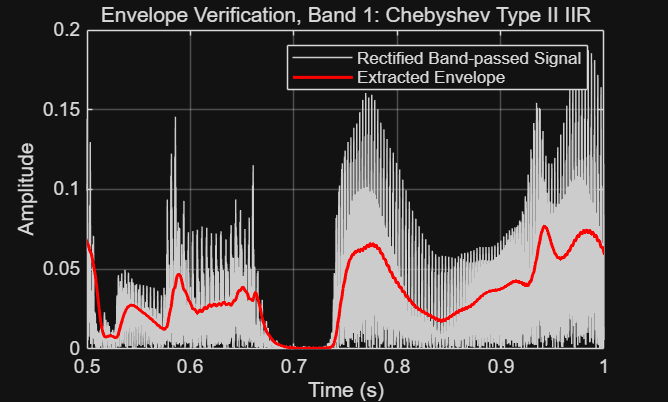

Chebyshev Type II IIR: input energy = 87.0316, before normalization = 19.7305, after normalization = 87.0316


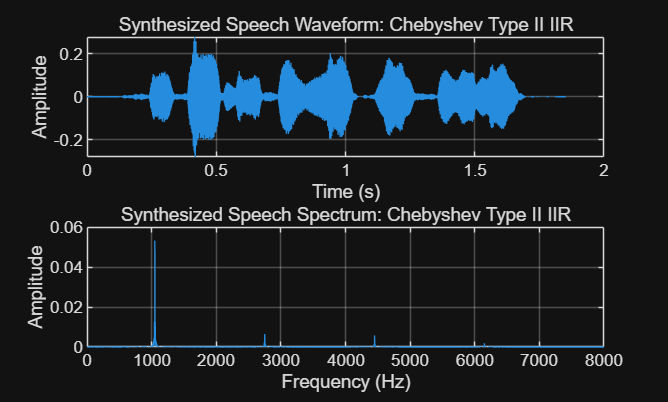


Running filter type: Elliptic IIR


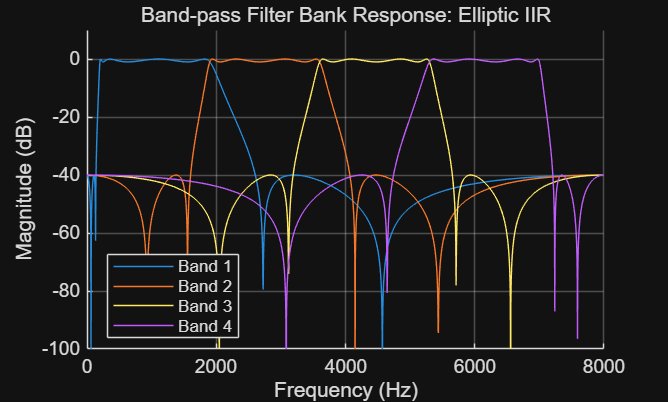

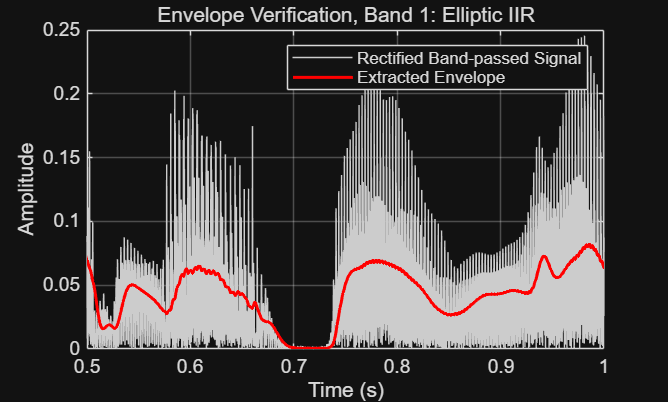

Elliptic IIR: input energy = 87.0316, before normalization = 27.3932, after normalization = 87.0316


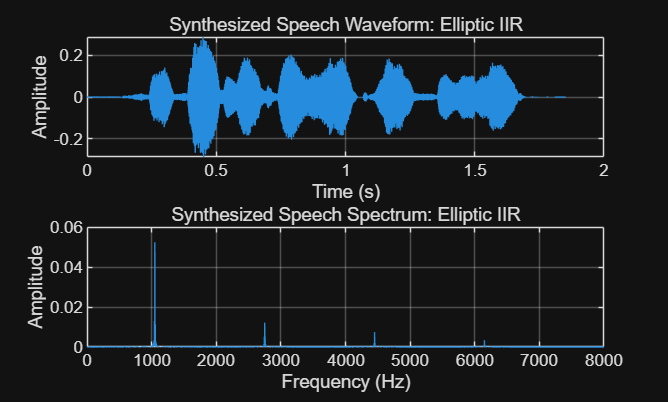


Running filter type: FIR Hamming Window


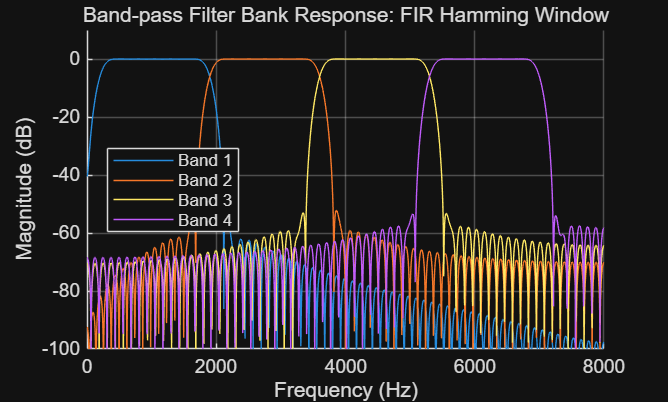

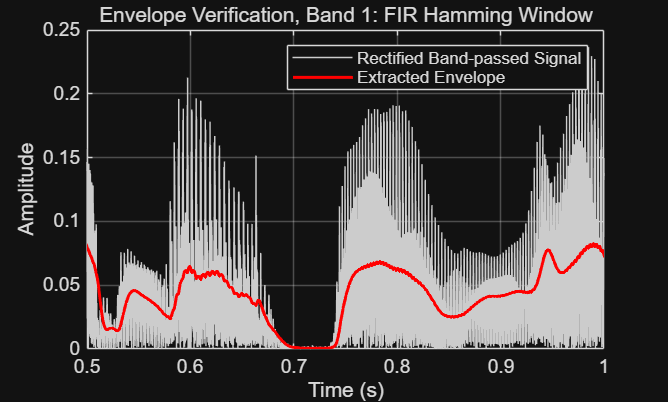

FIR Hamming Window: input energy = 87.0316, before normalization = 27.5111, after normalization = 87.0316


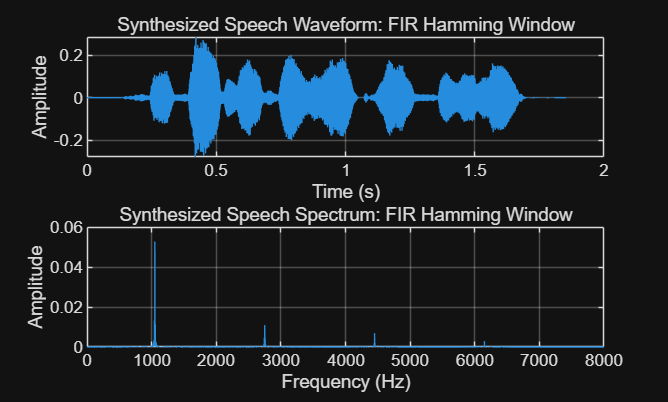

pause(0.5);


filter_types = {'butterworth_iir', 'cheby1_iir', 'cheby2_iir', 'elliptic_iir', 'fir_hamming'};

filter_labels = {'Butterworth IIR', ...
                 'Chebyshev Type I IIR', ...
                 'Chebyshev Type II IIR', ...
                 'Elliptic IIR', ...
                 'FIR Hamming Window'};

all_outputs = cell(length(filter_types), 1);
energy_result = zeros(length(filter_types), 3);



for fidx = 1:length(filter_types)

    filter_type = filter_types{fidx};
    filter_label = filter_labels{fidx};

    fprintf('\nRunning filter type: %s\n', filter_label);



    figure('Name', ['Filter Bank Response - ', filter_label]);
    hold on;

    for i = 1:N
        Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
        [B_bp, A_bp] = design_bandpass_filter(filter_type, Wn);

        [H, F] = freqz(B_bp, A_bp, 2048, fs);
        plot(F, 20 * log10(abs(H) + eps));
    end

    hold off;
    title(['Band-pass Filter Bank Response: ', filter_label]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    xlim([0, 8000]);
    ylim([-100, 10]);
    grid on;
    legend('Band 1', 'Band 2', 'Band 3', 'Band 4', 'Location', 'best');

    exportgraphics(gcf, sprintf('Additional_Task3_filter_response_%s.png', filter_type), 'Resolution', 300); 
    pause(0.5);


    y_sum = zeros(1, L);

    for i = 1:N

        Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);

        [B_bp, A_bp] = design_bandpass_filter(filter_type, Wn);

        y_band = filter(B_bp, A_bp, vocoder_input);

        y_rectified = abs(y_band);

        y_envelope = filter(b_lpf, a_lpf, y_rectified);

        if i == 1
            figure('Name', ['Envelope Verification - ', filter_label]);

            plot(t, y_rectified, 'Color', [0.8 0.8 0.8]);
            hold on;
            plot(t, y_envelope, 'r', 'LineWidth', 1.5);
            hold off;

            title(['Envelope Verification, Band 1: ', filter_label]);
            xlabel('Time (s)');
            ylabel('Amplitude');
            legend('Rectified Band-passed Signal', 'Extracted Envelope');
            xlim([0.5, 1.0]);
            grid on;

            exportgraphics(gcf, sprintf('Additional_Task3_envelope_%s.png', filter_type), 'Resolution', 300); 
            pause(0.5);
        end

        sine_wave = sin(2 * pi * center_freq(i) * t);

        y_modulated = y_envelope .* sine_wave;

        y_sum = y_sum + y_modulated;

    end



    e_input = sum(vocoder_input .^ 2);
    e_before = sum(y_sum .^ 2);

    y_synth = y_sum * sqrt(e_input / (e_before + eps));

    e_after = sum(y_synth .^ 2);

    energy_result(fidx, :) = [e_input, e_before, e_after];

    all_outputs{fidx} = y_synth;

    fprintf('%s: input energy = %.4f, before normalization = %.4f, after normalization = %.4f\n', ...
        filter_label, e_input, e_before, e_after);



    filename = sprintf('Additional_Task3_filter_%s_N%d_LPF%dHz.wav', ...
        filter_type, N, LPF_cut_freq);

    audiowrite(filename, y_synth, fs);



    figure('Name', ['Synthesized Signal - ', filter_label]);

    subplot(2,1,1);
    plot(t, y_synth);
    title(['Synthesized Speech Waveform: ', filter_label]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    subplot(2,1,2);
    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

    plot(f, P_single);
    title(['Synthesized Speech Spectrum: ', filter_label]);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    xlim([0, 8000]);
    grid on;

    exportgraphics(gcf, sprintf('Additional_Task3_synthesized_%s.png', filter_type), 'Resolution', 300); 
    pause(0.5);
end

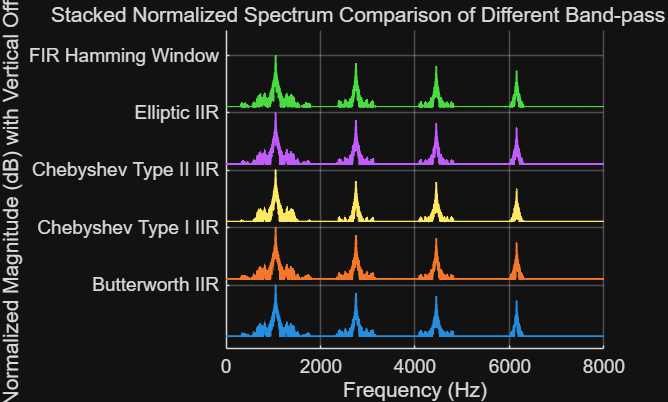




figure('Name', 'Spectrum Comparison of Different Band-pass Filters', 'Renderer', 'painters');
hold on;

offset_step_db = 90; 
for fidx = 1:length(filter_types)

    y_synth = all_outputs{fidx};

    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

  
    P_norm = P_single / (max(P_single) + eps);

  
    P_db = 20 * log10(P_norm + eps);

    P_db(P_db < -80) = -80;


    P_db_shifted = P_db + (fidx - 1) * offset_step_db;

    plot(f, P_db_shifted, 'LineWidth', 1.0);

end

hold off;

title('Stacked Normalized Spectrum Comparison of Different Band-pass Filter Types');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude (dB) with Vertical Offset');
xlim([0, 8000]);

yticks((0:length(filter_labels)-1) * offset_step_db);
yticklabels(filter_labels);

grid on;

exportgraphics(gcf, 'Additional_Task3_spectrum_comparison.png', 'Resolution', 300);

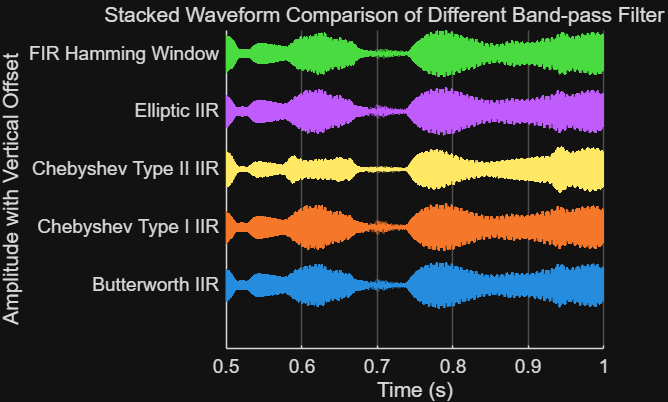

pause(0.5);

t_start = 0.5;
t_end = 1.0;

idx = find(t >= t_start & t <= t_end);


max_plot_points = 4000;
plot_step = max(1, floor(length(idx) / max_plot_points));
idx_plot = idx(1:plot_step:end);


max_amp = 0;
for fidx = 1:length(filter_types)
    max_amp = max(max_amp, max(abs(all_outputs{fidx}(idx_plot))));
end

offset_step = 2.5 * (max_amp + eps);

figure('Name', 'Waveform Comparison of Different Band-pass Filters', 'Renderer', 'painters');
hold on;

for fidx = 1:length(filter_types)
    y_plot = all_outputs{fidx}(idx_plot) + (fidx - 1) * offset_step;
    plot(t(idx_plot), y_plot, 'LineWidth', 1.0);
end

hold off;
title('Stacked Waveform Comparison of Different Band-pass Filter Types');
xlabel('Time (s)');
ylabel('Amplitude with Vertical Offset');
yticks((0:length(filter_labels)-1) * offset_step);
yticklabels(filter_labels);
grid on;

exportgraphics(gcf, 'Additional_Task3_waveform_comparison.png', 'Resolution', 300);

pause(0.5);


energy_table = table(filter_labels', energy_result(:,1), energy_result(:,2), energy_result(:,3), ...
    'VariableNames', {'Filter_Type', 'Input_Energy', 'Energy_Before_Normalization', 'Energy_After_Normalization'});

disp('Energy verification result:');

Energy verification result:


disp(energy_table);

           Filter_Type           Input_Energy    Energy_Before_Normalization    Energy_After_Normalization
    _________________________    ____________    ___________________________    __________________________

    {'Butterworth IIR'      }       87.032                  28.75                         87.032          
    {'Chebyshev Type I IIR' }       87.032                  26.82                         87.032          
    {'Chebyshev Type II IIR'}       87.032                 19.731                         87.032          
    {'Elliptic IIR'         }       87.032                 27.393                         87.032          
    {'FIR Hamming Window'   }       87.032                 27.511                         87.032          




writetable(energy_table, 'Additional_Task3_energy_verification.csv');

disp('Additional Task 3 finished.');

Additional Task 3 finished.





function [B, A] = design_bandpass_filter(filter_type, Wn)

    switch filter_type

        case 'butterworth_iir'
            filter_order = 4;
            [B, A] = butter(filter_order, Wn, 'bandpass');

        case 'cheby1_iir'
            filter_order = 4;
            passband_ripple_db = 1;
            [B, A] = cheby1(filter_order, passband_ripple_db, Wn, 'bandpass');

        case 'cheby2_iir'
            filter_order = 4;
            stopband_attenuation_db = 40;
            [B, A] = cheby2(filter_order, stopband_attenuation_db, Wn, 'bandpass');

        case 'elliptic_iir'
            filter_order = 4;
            passband_ripple_db = 1;
            stopband_attenuation_db = 40;
            [B, A] = ellip(filter_order, passband_ripple_db, stopband_attenuation_db, Wn, 'bandpass');

        case 'fir_hamming'
            fir_order = 128;
            B = fir1(fir_order, Wn, 'bandpass', hamming(fir_order + 1));
            A = 1;

        otherwise
            error('Unknown filter type: %s', filter_type);

    end

end